rng(1);
dcl_init;
pkt_size = 10^5;
k = 2;
M = 4;
modulation = 'psk';

## Part 2:

### 1.

b_tx = bit_gen(pkt_size, k);

### 2. 

b_gray = gray_code(k);

b_tx_dec = bi2de(b_tx, 'left-msb');
[cons, ~] = constellation(M, modulation);

flag_gray_encode = 1;
if flag_gray_encode == 1
    sym_idx = zeros(pkt_size, 1);
    b_gray_dec = bi2de(b_gray, 'left-msb');
    for c = 1:M
        sym_idx(b_tx_dec == b_gray_dec(c)) = c;
    end
    mod_sym = cons(sym_idx);
else
    sym_idx = b_tx_dec + 1
    mod_sym = cons(sym_idx);
end

### 3.

pulse_name = 'triangular';
pulse_shape_mode = 'kron';
[tx_smpl1, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
% n = 1:pkt_size * smpl_per_symbl;
% plot(n, real(tx_smpl1))
% hold on
% plot(n, imag(tx_smpl1))
% hold off
% legend('real part', 'imaginary part', 'Location', 'south')
% title('kron mode')

pulse_shape_mode = 'conv';
[tx_smpl2, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
% plot(n, real(tx_smpl2))
% hold on
% plot(n, imag(tx_smpl2))
% hold off
% legend('real part', 'imaginary part', 'Location', 'south')
% title('conv mode')

## Part 3:

### 1.

tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl1];

### 2.

rx_smpl = tx_sampl_delayed * exp(1j * chnl_phase_offset);

### 3.

Es_avg = sum(abs(cons).^2) / M

Es_avg = 1

Eb = Es_avg / k

Eb = 0.5000


snr_db = 10;
var_noise = Eb / power(10, (snr_db / 10))

var_noise = 0.0500


l = length(tx_smpl1);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + rx_smpl;

## Part 4:

### 1.

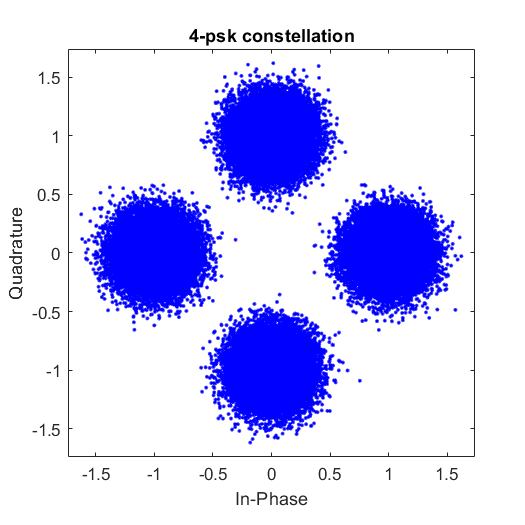

rx_smpl = rx_smpl_noise;
rx_mode = 'correlator';
[det_sym_idx1, rx_sym1] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym1)
title([num2str(M), '-', modulation, ' constellation'])


rx_mode = 'matched_filter';
[det_sym_idx2, rx_sym2] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);

### 2.

if flag_gray_encode == 1
    det_bit = b_gray(det_sym_idx2, :);
else
    det_bit = de2bi(det_sym_idx2-1, 'left-msb');
end

### 3.

ser = sum(det_sym_idx2 ~= sym_idx) / pkt_size

ser = 0

### 4.

ber = sum((det_bit ~= b_tx), 'all') / (pkt_size * k)

ber = 0

## Part 5:

### 1.

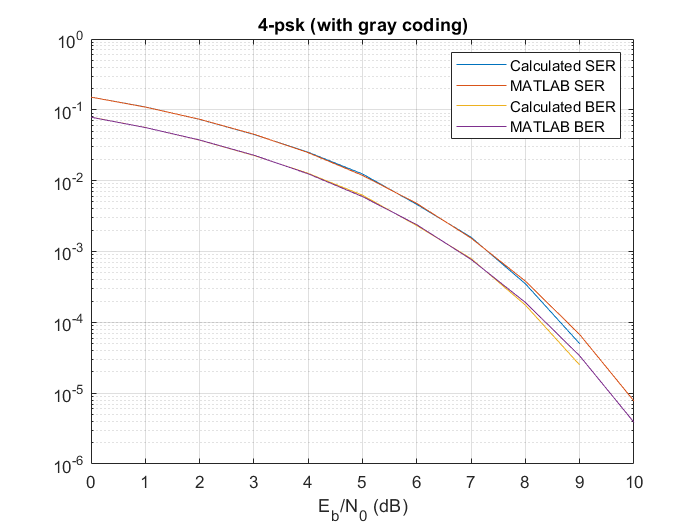

EbN0 = 0:10;
p1_s = zeros(11, 1);
var_noise = Eb ./ power(10, (EbN0 / 10));
rx_mode = 'correlator';
for c = 1:11
    noise_smpl = (sqrt(var_noise(c)/2) * randn(l, 1) + 1j * sqrt(var_noise(c)/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + tx_smpl1;
    rx_smpl = rx_smpl_noise;
    [det_sym_idx1, rx_sym1] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_gray(det_sym_idx1, :);
    p1_s(c) = sum(det_sym_idx1 ~= sym_idx) / pkt_size;
    if flag_gray_encode == 1
        det_bit = b_gray(det_sym_idx1, :);
    else
        det_bit = de2bi(det_sym_idx1-1, 'left-msb');
    end
    p1_b(c) = sum((det_bit ~= b_tx), 'all') / (pkt_size * k);
end
[p2_b, p2_s] = berawgn((EbN0).', modulation, M, 'nondiff');

figure
semilogy(EbN0, p1_s)
hold on
semilogy(EbN0, p2_s)
hold on
semilogy(EbN0, p1_b)
hold on
semilogy(EbN0, p2_b)
hold off
legend('Calculated SER', 'MATLAB SER', 'Calculated BER', 'MATLAB BER')
title([num2str(M), '-', modulation , ' (with gray coding)'])
xlabel('E_b/N_0 (dB)')
grid

#### 16 QAM:

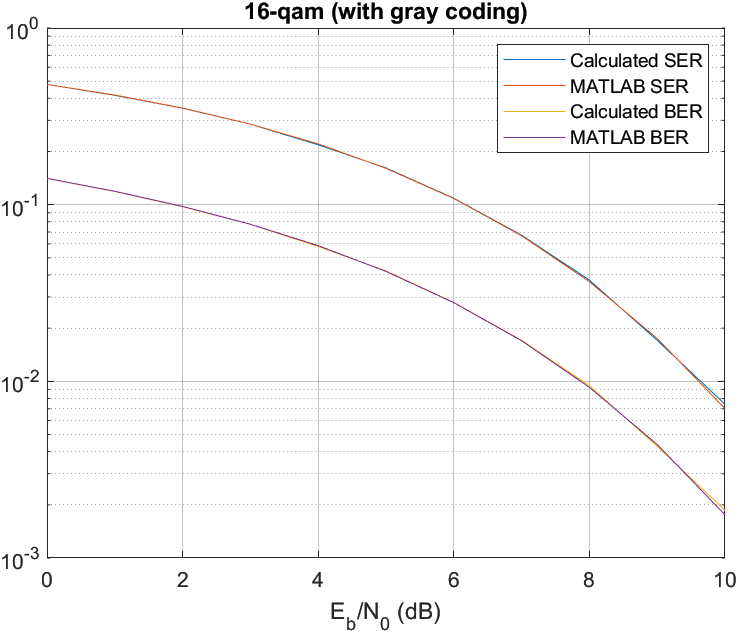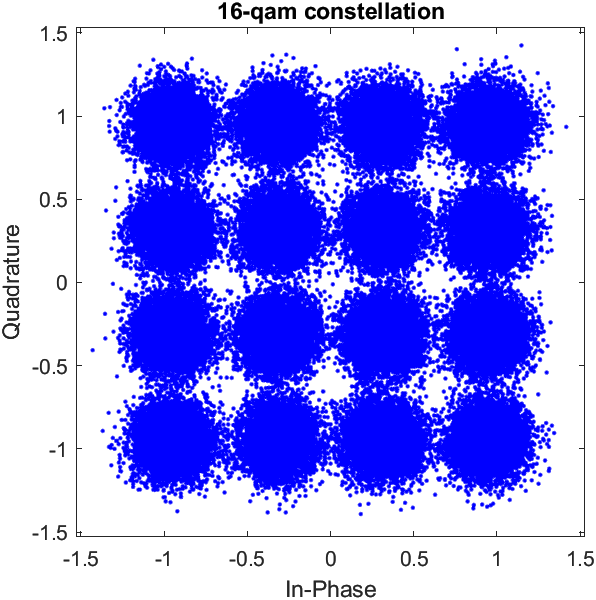

#### 8 PSK:

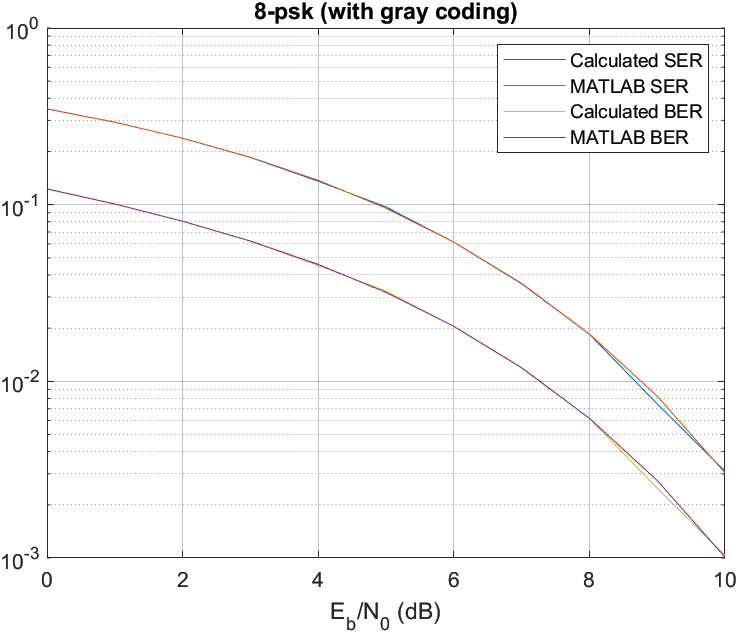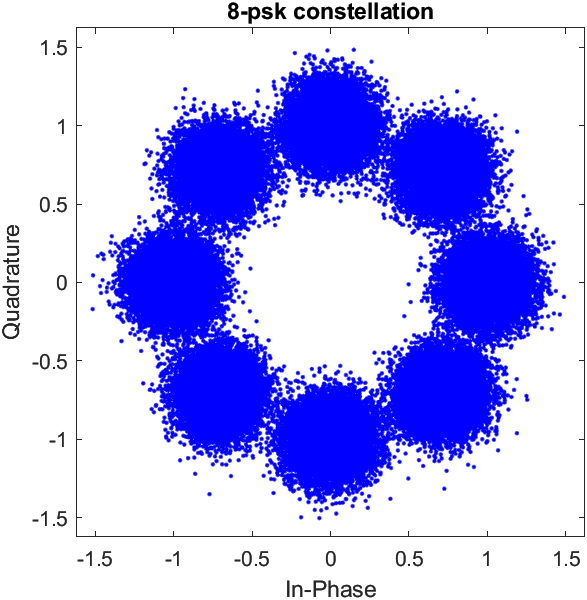

#### 4 PAM:

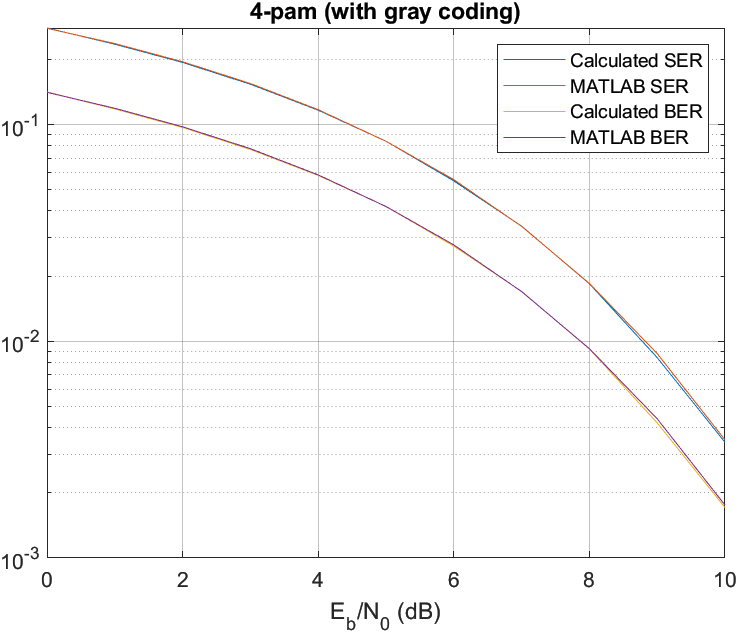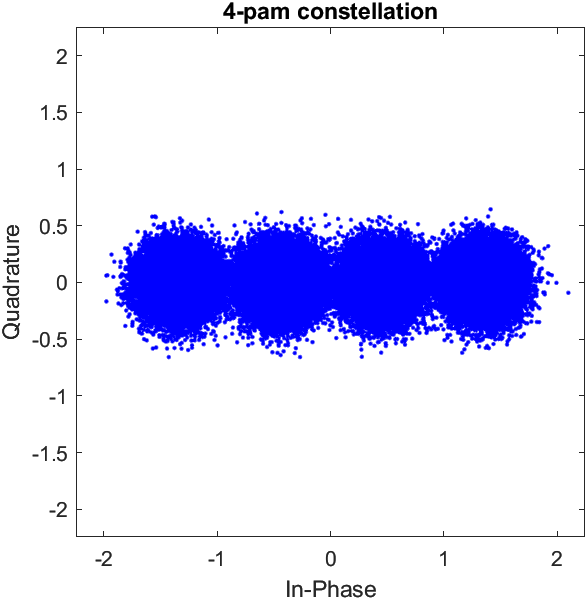

### 2. setp 1:

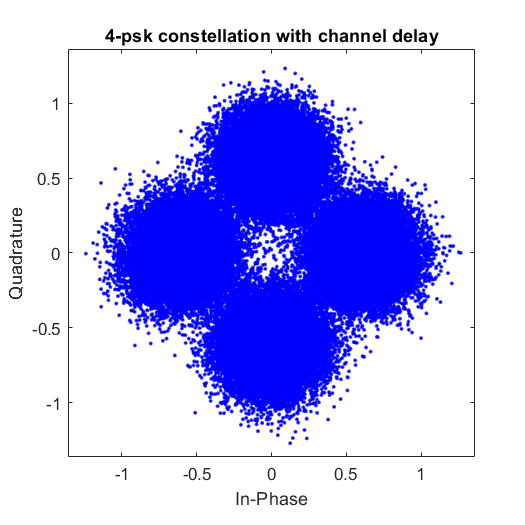

chnl_delay_in_smpl = fix(0.8*smpl_per_symbl);
tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl1];

Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
snr_db = 10;
var_noise = Eb / power(10, (snr_db / 10));

l = length(tx_sampl_delayed);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + tx_sampl_delayed;

rx_smpl = rx_smpl_noise;
rx_mode = 'correlator';
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)
title([num2str(M), '-', modulation, ' constellation with channel delay'])


det_bit = b_gray(det_sym_idx, :);

ser = sum(det_sym_idx(1:length(sym_idx), 1) ~= sym_idx) / pkt_size

ser = 0.7503

ber = sum((det_bit(1:length(b_tx), :) ~= b_tx), 'all') / (pkt_size * k)

ber = 0.4998

#### without channel delay:

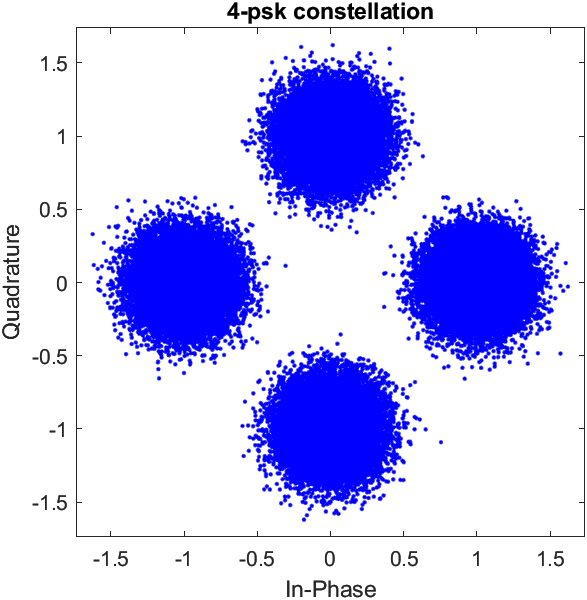

#### coefficient of channel delay 0.1:

ser = ${10}^{-5}$

ber = $5\times {10}^{-6}$

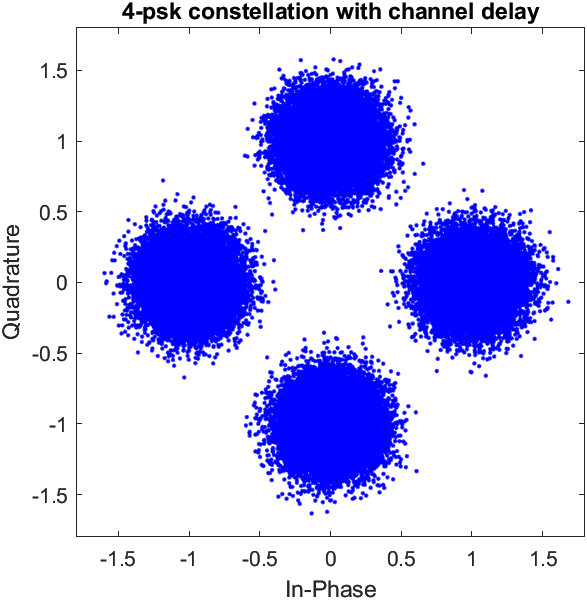

fix(0.1*8) = 0 , In this part we have no channel delay and we can see that constellation is the same as the first figure.

#### coefficient of channel delay 0.5:

ser = 0.4459

ber = 0.2547

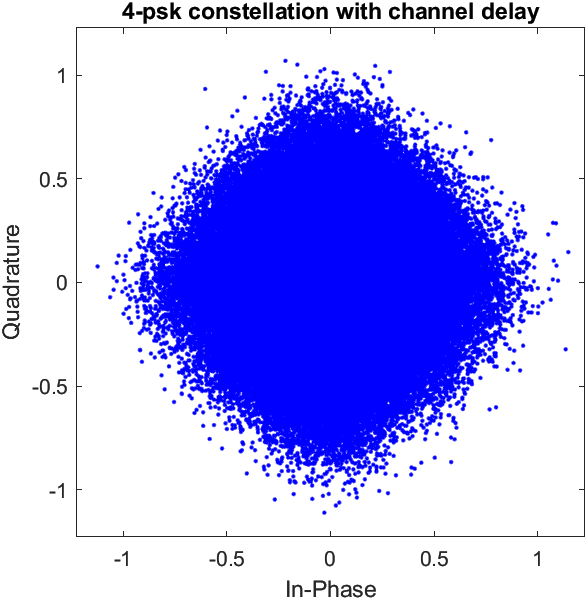

fix(0.5*8) = 4, In this part each symbol has half of its transfered symbol and as the constellation shows, there is no border between different symbols and BER and SER increase.

#### coefficient of channel delay 0.8:

ser = 0.7503

ber = 0.4998

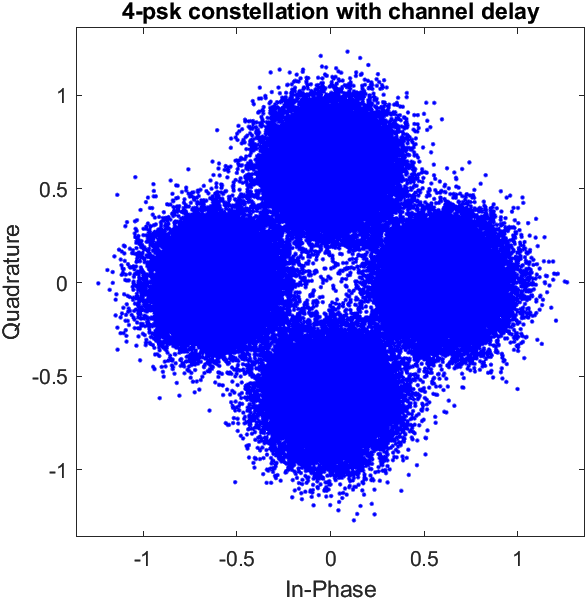

fix(0.8*8) = 6, In this part each symbol has lost 6 of its transfered samples, so BER and SER increase.

Because 6 samples of a symbol will demodulate with 2 samples from another symbol. As the constellation shows, the border between different symbols is distinguishable.

#### 2. step 2, 3:

rx_alg = 1;
hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
hder_dec = bi2de(hder_bit, 'left-msb');

b_tx_dec = bi2de(b_tx, 'left-msb');
hder_b_tx_dec = [hder_dec; b_tx_dec];

sym_idx = zeros(pkt_size, 1);
b_gray_dec = bi2de(b_gray, 'left-msb');
for c = 1:M
    sym_idx(hder_b_tx_dec == b_gray_dec(c)) = c;
end
mod_sym = cons(sym_idx);

pulse_name = 'triangular';
pulse_shape_mode = 'kron';
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
hdr_smpl = tx_smpl(1:length(hder_dec)*smpl_per_symbl);

chnl_delay_in_smpl = fix(0.5*smpl_per_symbl);
tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];

Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
snr_db = 10;
var_noise = Eb / power(10, (snr_db / 10));

l = length(tx_sampl_delayed);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + tx_sampl_delayed;

[c, lags] = xcorr(hdr_smpl, rx_smpl_noise);
hdr_corr_max = max(abs(xcorr(hdr_smpl, hdr_smpl)))

hdr_corr_max = 108

corr_out_rx_max = max(abs(c))

corr_out_rx_max = 109.0068

idx_max = length(rx_smpl_noise) - find(abs(c) == corr_out_rx_max) + 1

idx_max = 5

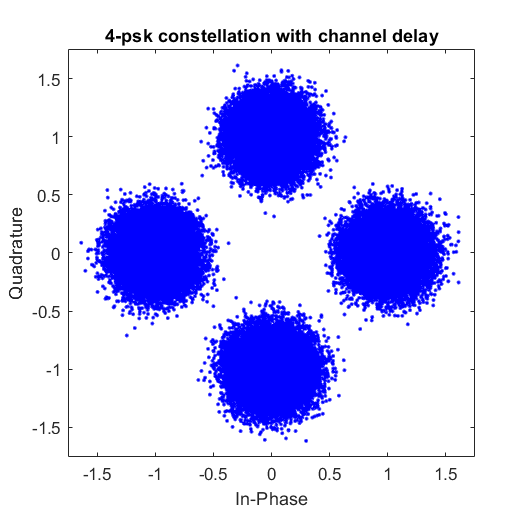


rx_smpl = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1);
rx_mode = 'correlator';
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)
title([num2str(M), '-', modulation, ' constellation with channel delay'])


det_bit = b_gray(det_sym_idx, :);

ser = sum(det_sym_idx(1:length(rx_sym), 1) ~= sym_idx(length(hder_dec) + 1:end, 1)) / (pkt_size)

ser = 1.0000e-05

ber = sum((det_bit(1:length(b_tx), :) ~= b_tx), 'all') / (pkt_size * k)

ber = 5.0000e-06

#### Comparing the results with previous part, we can see that in this part we get the same results as there is no delay.

###  3. step 1:

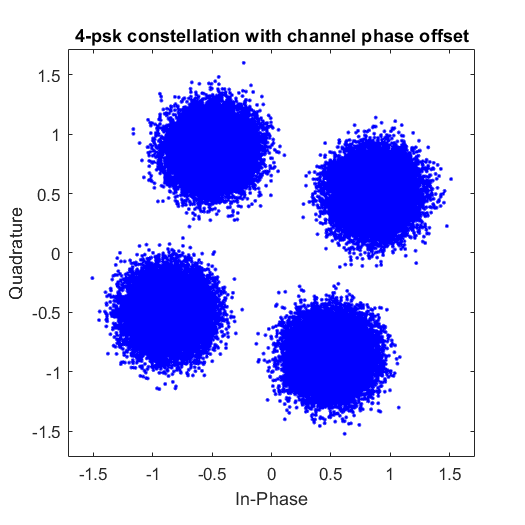

chnl_phase_offset = pi / 6;
b_tx_dec = bi2de(b_tx, 'left-msb');

sym_idx = zeros(pkt_size, 1);
b_gray_dec = bi2de(b_gray, 'left-msb');
for c = 1:M
    sym_idx(b_tx_dec == b_gray_dec(c)) = c;
end
mod_sym = cons(sym_idx);

pulse_name = 'triangular';
pulse_shape_mode = 'kron';
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);

l = length(tx_smpl);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + tx_smpl;

rx_smpl = rx_smpl_noise * exp(1j * chnl_phase_offset);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)
title([num2str(M), '-', modulation, ' constellation with channel phase offset'])


det_bit = b_gray(det_sym_idx, :);

ser = sum(det_sym_idx ~= sym_idx) / (pkt_size)

ser = 0.0514

ber = sum((det_bit ~= b_tx), 'all') / (pkt_size * k)

ber = 0.0257

#### As we can see, the constellation is rotated about pi/6 rad. BER will increase, as the channel has a phase offset and it will move the demodulated symbols.

#### 3. step 2:

hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
hder_dec = bi2de(hder_bit, 'left-msb');

b_tx_dec = bi2de(b_tx, 'left-msb');
hder_b_tx_dec = [hder_dec; b_tx_dec];

sym_idx = zeros(pkt_size, 1);
b_gray_dec = bi2de(b_gray, 'left-msb');
for c = 1:M
    sym_idx(hder_b_tx_dec == b_gray_dec(c)) = c;
end
mod_sym = cons(sym_idx);

pulse_name = 'triangular';
pulse_shape_mode = 'kron';
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
hdr_smpl = tx_smpl(1:length(hder_dec)*smpl_per_symbl);

chnl_delay_in_smpl = fix(0.5*smpl_per_symbl);
tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
tx_sampl_delayed = tx_sampl_delayed * exp(1j * chnl_phase_offset); %phase offset

Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
snr_db = 10;
var_noise = Eb / power(10, (snr_db / 10));

l = length(tx_sampl_delayed);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + tx_sampl_delayed;

[c, lags] = xcorr(hdr_smpl, rx_smpl_noise);
hdr_corr_max = max(abs(xcorr(hdr_smpl, hdr_smpl)))

hdr_corr_max = 108

[corr_out_rx_max, idx] = max(c)

corr_out_rx_max = 91.8055 - 54.7483i

idx = 800864

ang = angle(corr_out_rx_max)

ang = -0.5377

idx_max = length(rx_smpl_noise) - idx + 1

idx_max = 5

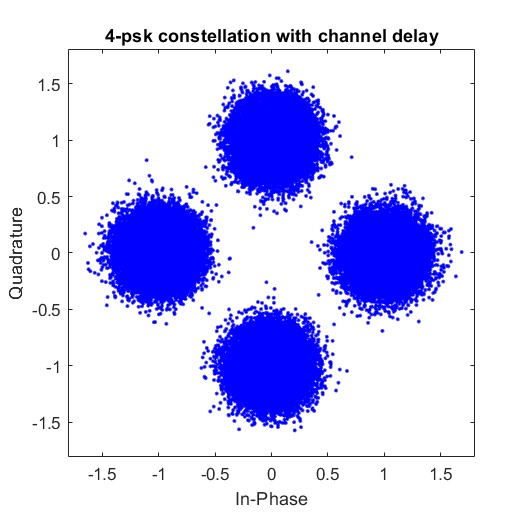


rx_smpl = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1) * exp(1j * ang);
rx_mode = 'correlator';
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)
title([num2str(M), '-', modulation, ' constellation with channel delay'])


det_bit = b_gray(det_sym_idx, :);

ser = sum(det_sym_idx(1:length(rx_sym), 1) ~= sym_idx(length(hder_dec) + 1:end, 1)) / (pkt_size)

ser = 0

ber = sum((det_bit(1:length(b_tx), :) ~= b_tx), 'all') / (pkt_size * k)

ber = 0

#### According to xcorr function, as the second input is rx_smpl_noise , angle of rx_smpl_noise will be nagetive in output. Phase offset will be removed by multiplying the angle of peak and rx.

## Functions Definition:

### part 1.

#### 1.

function [b] = bit_gen(N, k)
b = int32(randi([0, 1], [N, k]));
end

#### 2.

#### gray code

function [b_gray] = gray_code(k)
b_gray = ones(2^k, k);
b_gray(1:2^(k-1), 1) = 0;
if k ~= 1
    tmp = gray_code(k-1);
    b_gray(1:2^(k-1), 2:k) = tmp;
    b_gray(2^(k-1) + 1:2^k, 2:k) = flip(tmp, 1);
end
end

#### constellation

function [cons, Es_avg] = constellation(M, modulation)
if strcmp(modulation, 'pam')
    Es_avg = (M^2 - 1)/3;
    cons = (-M+1:2:M-1).'/ sqrt(Es_avg);
elseif strcmp(modulation, 'psk')
    m = (1:M).';
    cons = cos(2*pi*(m-1)/M) + 1j * sin(2*pi*(m-1)/M);
elseif strcmp(modulation, 'qam')
    m1 = fix(log2(M) / 2);
    m2 = log2(M) - m1;
    v1 = 1j * (-2^m1+1:2:2^m1-1).';
    v2 = (-2^m2+1:2:2^m2-1);
    cons = ones(M, 1);
    for k = 1:2^m2
        if mod(k, 2) == 0
            cons(2^m1 * (k-1) + 1:2^m1 * k, 1) = v1 + v2(k) * ones(2^m1, 1);
        else
            cons(2^m1 * (k-1) + 1:2^m1 * k, 1) = flip(v1) + v2(k) * ones(2^m1, 1);
        end
    end
    Es_avg = sum(abs(cons).^2) / M;
    cons = cons / sqrt(Es_avg);
end
Es_avg = 1;
end

#### 3.

#### pulse shape

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
Ts = smpl_per_symbl * fs;
t = (0:smpl_per_symbl-1)/fs;
if strcmp(pulse_name, 'rectangular')
    p = ones(smpl_per_symbl, 1);
elseif strcmp(pulse_name, 'triangular')
    p = (max(Ts/2 - abs(t-Ts/2), 0)).';
elseif strcmp(pulse_name, 'sine')
    p = sin(pi*t.'/Ts);
end
p = p / sqrt(sum(p.^2));
end

#### upsample

function [y] = upsmpl(x, N)
y = zeros(1, (length(x) - 1)*(N - 1) + length(x));
for i = 1:N:(length(x) - 1)*(N - 1) + length(x)
    y(i) = x((i - 1)/N + 1);
end
end

#### pulse modulation

function [tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_shape_mode, varargin)
[cons, ~] = constellation(M, modulation);
mod_sym = cons(sym_idx);
[p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl); 
if strcmp(pulse_shape_mode, 'kron')
    [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
    tx_smpl = kron(mod_sym, p);
elseif strcmp(pulse_shape_mode, 'conv')
    s = upsmpl(mod_sym, length(p));
    tx_smpl = conv(s, p).';
end
end

### part 2.

#### 1.

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
rx_sym = zeros(length(rx_smpl)/smpl_per_symbl, 1);
if strcmp(rx_mode, 'correlator')
    for c = 1:smpl_per_symbl:length(rx_smpl)
        rx_sym((c-1)/smpl_per_symbl + 1, 1) = sum(rx_smpl(c:c+smpl_per_symbl-1, 1) .* conj(p));
    end
elseif strcmp(rx_mode, 'matched_filter')
    tmp = conv(rx_smpl, flip(conj(p)), 'valid');
    rx_sym = tmp(1:smpl_per_symbl:end);
end
end

#### 2.

function [det_sym] = min_dist_detector(rx_sym, constellation)
[~, det_sym_idx] = min(abs(rx_sym - constellation.'), [], 2);
det_sym = constellation(det_sym_idx);
end

#### 3.

function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, varargin)
[p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
if mod(length(rx_smpl), smpl_per_symbl) == 0
   rx_sym = zeros(length(rx_smpl)/smpl_per_symbl, 1);
else
    rx_sym = zeros(fix(length(rx_smpl)/smpl_per_symbl) + 1, 1);
    rx_smpl = [rx_smpl; zeros(smpl_per_symbl - mod(length(rx_smpl), smpl_per_symbl), 1)];
end

if strcmp(rx_mode, 'correlator')
    for c = 1:smpl_per_symbl:length(rx_smpl)
        rx_sym((c-1)/smpl_per_symbl + 1, 1) = sum(rx_smpl(c:c+smpl_per_symbl-1, 1) .* conj(p));
    end
elseif strcmp(rx_mode, 'matched_filter')
    tmp = conv(rx_smpl, flip(conj(p)), 'valid');
    rx_sym = tmp(1:smpl_per_symbl:end);
end

[cons, ~] = constellation(M, modulation);
[~, det_sym_idx] = min(abs(rx_sym - cons.'), [], 2);
end